# Lab 3

## Q1

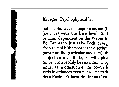

% read the photo
I_text=imread("text1.tif");
figure;
imshow(I_text);
%imtool(I_text);
title("text.tif");

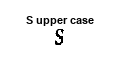

%manually getting the xy cordinats
ys=343;
xs=217;
%end cordinats
deltay=358-ys;
deltax=242-xs;
rectS=[ys xs deltay deltax];
%making the mask
S_Cap_mask=imcrop(I_text,rectS);
imshow(S_Cap_mask);
title("S upper case");

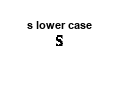

%manually getting the xy cordinats
ys=443;
xs=186;
%end cordinats
deltay=455-ys;
deltax=204-xs;
rects=[ys xs deltay deltax];
s_mask=imcrop(I_text,rects);
imshow(s_mask);
title("s lower case");

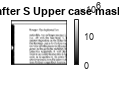

%debug


%output with the mask
output1=xcorr2(I_text,S_Cap_mask);
figure;
%use [] to get all the range of values, the default input is a double and the value
%range is 0:1. Therefor we use [].
imshow(output1,[]);
colorbar;
title("Output after S Upper case mask");

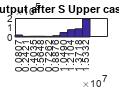

figure;
hist(output1(:));
title("Hist Output after S Upper case mask");

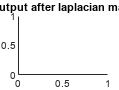

%using laplacian to find the differences in the photo
%laplacian mask
Lap_mask=fspecial("laplacian");

%using negative mask to reverse the values, we want the max value to be
%white color
output_Laplacian=xcorr2(output1,(-Lap_mask));
figure;
imtool(output_Laplacian,[]);
title("Output after laplacian mask");

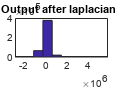

figure;
hist(output_Laplacian(:));
title("Hist Output after laplacian mask");

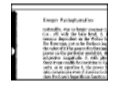

Normal_output_Laplacian=output_Laplacian/max(output_Laplacian,[],"all");
result_Laplacian=sum(Normal_output_Laplacian(:)>0.55);


%find lower case s
%output with the mask
output_s_lower=xcorr2(I_text,s_mask);
figure;
%use [] to get all the range of values, the default input is a double and the value
%range is 0:1. Therefor we use [].
imshow(output_s_lower,[]);
title("Output after s lower case mask");

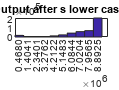

figure;
hist(output_s_lower(:));
title("Hist Output after s lower case mask");

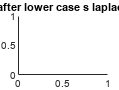


%using negative mask to reverse the values, we want the max value to be
%white color
output_Laplacian_lower=xcorr2(output_s_lower,(-Lap_mask));
figure;
imtool(output_Laplacian_lower,[]);
title("Output after lower case s laplacian mask");

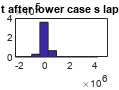

figure;
hist(output_Laplacian_lower(:));
title("Hist Output after lower case s laplacian mask");

Normal_output_Laplacian_lower=output_Laplacian_lower/max(output_Laplacian_lower,[],"all");
result_Laplacian_lower=sum(Normal_output_Laplacian_lower(:)>0.62);


## debug-make rectangle

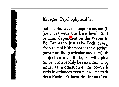

[R,C]=find(Normal_output_Laplacian>0.55);
figure;
imshow(I_text);
rectangle('Position',[R(1)-13, C(1)-8,13,8],'EdgeColor','r','LineWidth',1);
title("debug");

% rect_mark=ones(size(S_Cap_mask));
% rect_mark(1:end,1)=0;
% rect_mark(1:end,end)=0;
% rect_mark(1,1:end)=0;
% rect_mark(end,1:end)=0;



% %for later- use laplacian of gaussian
% log_Mask=fspecial("log");
% output_Log=xcorr2(output,(-log_Mask));
% figure;
% imshow(output_Log,[]);
% title("log");
% figure;
% hist(output_Log(:));
% figure;
% hist(output_Laplacian(:));


## Problem 2

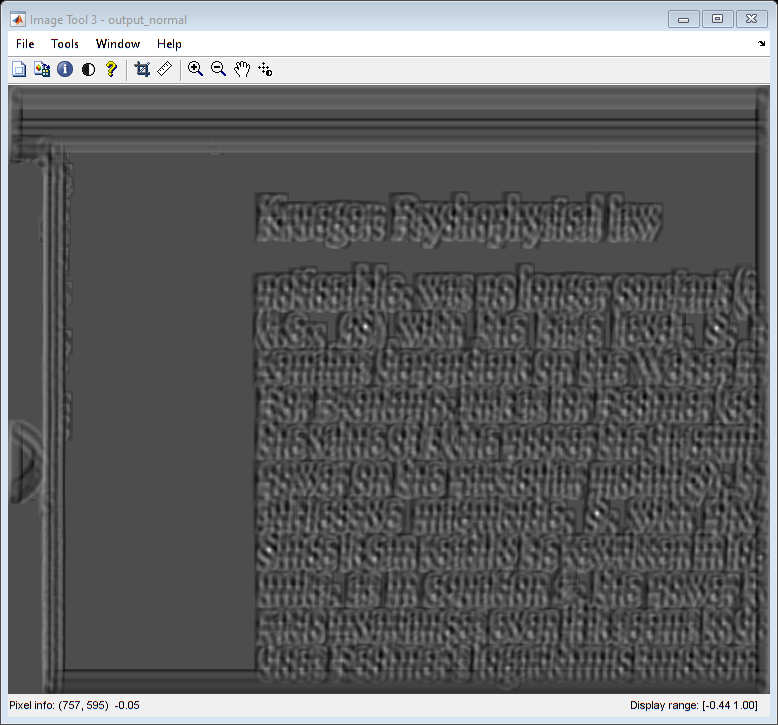

output_normal=normxcorr2(S_Cap_mask,I_text);
figure;
%display
imtool(output_normal,[]); %temp

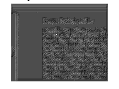

imshow(output_normal,[]);
title("output with normal");

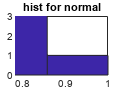

figure;

%count the number of deltas, find all values>0.79 and sum them. We found the
%smallest value using imtool which is 0.79.
result_normal=sum(output_normal(:)>0.79);
hist(output_normal(:));
xlim([0.78,1]);
ylim([0,3]);
title("hist for normal");

%[x,y]=ginput;
%I_text_out=xcorr2(I_text,)

## Problem 3

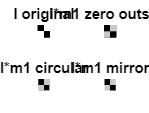

clc,clear,clf;
%create square image
I=zeros(50,50,'double');
%making white squares
I(1:25,26:50)=200;
I(26:50,1:25)=200;
%gray pixel at 12,12
I(13,13)=128;

figure;
subplot(2,2,1);
imshow(I);
title("I original");
%indexes are (rows-1,cols-1) meaning what we count from 0,0.

%averaging mask, I don't know if it should be a double.
m1=ones(3,3,'double')*1/9;
%Assumptions for each output:
%a. All the values outside the photo are 0.
%b. The filtering uses circular convolution, meaning that the photo is
%duplicated in the plane.
%c. The values outside the photo are reflection of the values inside the
%photo.

%a. zero outside the photo
out1=conv2(I,m1,'same');
subplot(2,2,2);
imshow(out1,[0 255]);
title('I*m1 zero outside');


%b. circular
I_circular=padarray(I,[2 2],"circular");
out2=conv2(I_circular,m1,'same');
out2=out2(3:end-2,3:end-2);
subplot(2,2,3);
imshow(out2,[0 255]);
title('I*m1 circular');

%c. mirror
I_mirror=padarray(I,[2 2],"symmetric");
out3=conv2(I_mirror,m1,'same');
out3=out3(3:end-2,3:end-2);
subplot(2,2,4);
imshow(out3,[0 255]);
title('I*m1 mirror');

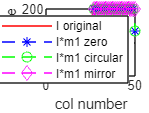


%4
figure;
colaxis=double(1:50);
plot(I(13,1:50),'r');
xlabel("col number");
ylabel("gray value");
hold on;
plot(out1(13,1:50),'b--*');
plot(out2(13,1:50),'g--o');
plot(out3(13,1:50),'m--diamond')
grid on;
legend('I original','I*m1 zero','I*m1 circular','I*m1 mirror');
hold off;

## Problem 4

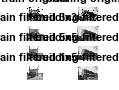

% reading the photos.
figure;
subplot(4,2,1);  % train original
I_t=imread("train.jpg");
imshow(I_t,[0 255]); title("train original");
subplot(4,2,2); % bulding original
I_b=imread("building.jpg");
imshow(I_b,[0 255]); title("bulding original");
subplot(4,2,3); % train filtered 3x3
I_t_3x3=medfilt2(I_t,[3 3]);
imshow(I_t_3x3,[0 255]); title("train filtered 3x3");
subplot(4,2,4); % building filtered 3x3
I_b_3x3=medfilt2(I_b,[3 3]);
imshow(I_b_3x3,[0 255]); title("building filtered 3x3");
subplot(4,2,5); % train filtered 5x5
I_t_5x5=medfilt2(I_t,[5 5]);
imshow(I_t_5x5,[0 255]); title("train filtered 5x5");
subplot(4,2,6); % building filtered 5x5
I_b_5x5=medfilt2(I_b,[5 5]);
imshow(I_b_5x5,[0 255]); title("building filtered 5x5");
subplot(4,2,7); % train filtered 1x5
I_t_1x5=medfilt2(I_t,[1 5]);
imshow(I_t_1x5,[0 255]); title("train filtered 1x5");
subplot(4,2,8); % building filtered 1x5
I_b_1x5=medfilt2(I_b,[1 5]);
imshow(I_b_1x5,[0 255]); title("building filtered 1x5");

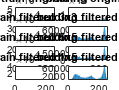


figure;
subplot(4,2,1); % hist for train original
h1=hist(I_t(:),0:255);bar(0:255,h1); axis([0 255 min(h1) max(h1)]);title("train original");
subplot(4,2,2); % hist for bulding original
h2=hist(I_b(:),0:255);bar(0:255,h2); axis([0 255 min(h2) max(h2)]);title("bulding original");
subplot(4,2,3); % hist for train filtered 3x3
h3=hist(I_t_3x3(:),0:255);bar(0:255,h3); axis([0 255 min(h3) max(h3)]);title("train filtered 3x3");
subplot(4,2,4); % hist for building filtered 3x3
h4=hist(I_b_3x3(:),0:255);bar(0:255,h4); axis([0 255 min(h4) max(h4)]);title("bulding filtered 3x3");
subplot(4,2,5); % hist for train filtered 5x5
h5=hist(I_t_5x5(:),0:255);bar(0:255,h5); axis([0 255 min(h5) max(h5)]);title("train filtered 5x5");
subplot(4,2,6); % hist for building filtered 5x5
h6=hist(I_b_5x5(:),0:255);bar(0:255,h6); axis([0 255 min(h6) max(h6)]);title("bulding filtered 5x5");
subplot(4,2,7); % hist for train filtered 1x5
h7=hist(I_t_1x5(:),0:255);bar(0:255,h7); axis([0 255 min(h7) max(h7)]);title("train filtered 1x5");
subplot(4,2,8); % hist for building filtered 1x5
h8=hist(I_b_1x5(:),0:255);bar(0:255,h8); axis([0 255 min(h8) max(h8)]);title("bulding filtered 1x5");

## Problem 5

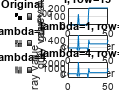

%laplacian mask from Lecture 5 page 41
Lap_mask=[0 -1 0;-1 4 -1;0 -1 0];
Q5_result1=figure();
subplot(3,2,1);
imshow(I,[]);
colorbar;
title("I Original");
subplot(3,2,3);
LapOutI=conv2(I,Lap_mask,'same');
%lambda=1
Q5OutI1=LapOutI+I;
imshow(Q5OutI1,[]);
title("Lambda=1");
colorbar;
subplot(3,2,5);
%lambda=4
Q5OutI4=4*LapOutI+I;
imshow(Q5OutI4,[]);
title("Lambda=4");
colorbar;

subplot(3,2,2);
plot(I(13,1:50));
title("I, row=13");
xlabel("col number");
ylabel("gray value");
grid on;

subplot(3,2,4);
plot(Q5OutI1(13,1:50));
title("lambda=1, row=13");
xlabel("col number");
ylabel("gray value");
grid on;

subplot(3,2,6);
plot(Q5OutI4(13,1:50));
title("lambda=4, row=13");
xlabel("col number");
ylabel("gray value");
grid on;
saveas(Q5_result1,"Q5_result1",'jpg');

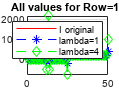

Q5_result2=figure();
plot(I(13,1:50),'r');
hold on;
plot(Q5OutI1(13,1:50),'b--*');
plot(Q5OutI4(13,1:50),'g--diamond')
grid on;
title("All values for Row=13");
legend('I original','lambda=1','lambda=4');
saveas(Q5_result2,"Q5_result2",'jpg');